# Improve Precision

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

load ./data/psdsig.mat
sig = 1e-3*sin(2*pi*fr*t);
n = length(sig)

n = 2400

## Task 1

The slider in the script controls the number of DFT points used by `periodogram`. The error is displayed in the script in the variable `e`.

In general, a larger number of DFT points will reduce the error. But as you saw in the previous page, the error depends on if the multiples of *f**s/N* are located near the fan's rotating frequency `fr`.

nfft = 2^(11)

nfft = 2048

[p, f] = periodogram(sig, ones(n, 1), nfft, fs);

This code plots the spectrum and calculates the error.

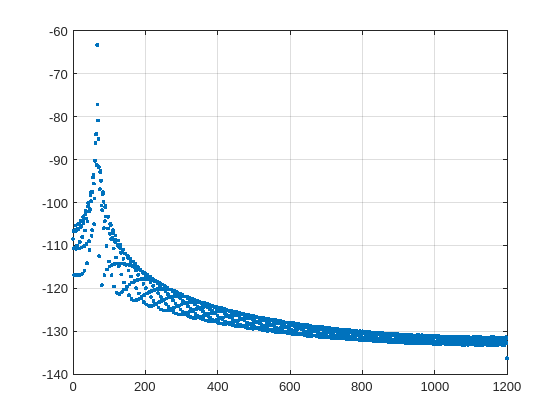

pwr = 10*log10(p);
figure;
plot(f, pwr, ".")
grid on

[peak, loc] = findpeaks(pwr, f, "NPeaks", 1, "SortStr", "descend")

peak = -63.2676

loc = 66.7969

e = abs(fr - loc)

e = 0.1302